Testing whether inverse filter method is robust to noise 

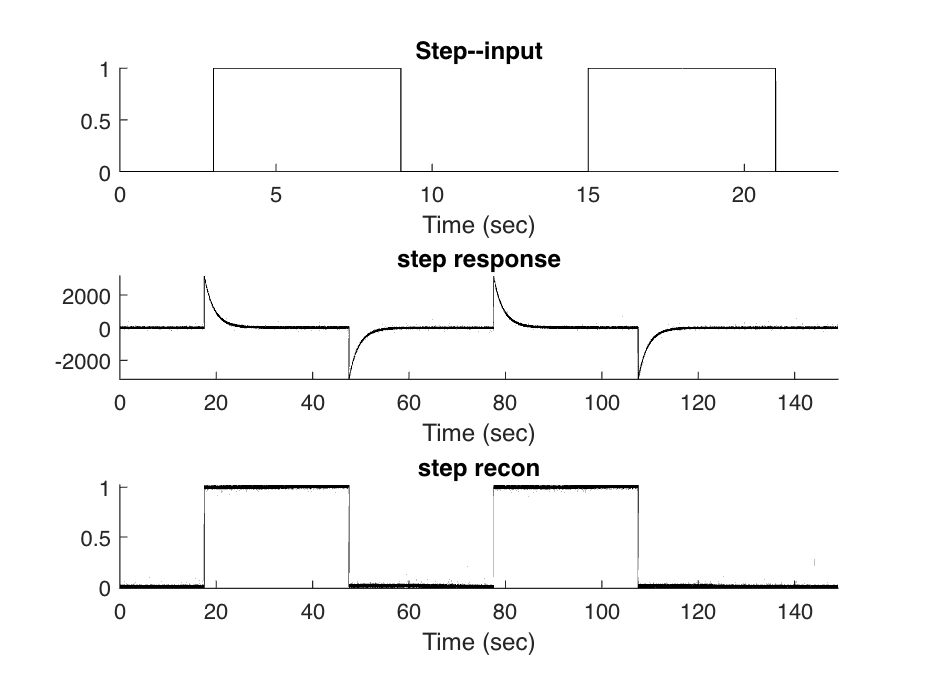

addpath(genpath('signals'))
addpath('signal_proc_functions')

% Load step input and recorded response and UIR
output = load('output_step.mat');
input = load('input_step.mat');
load('unit_impulse_response.mat', 'unit_impulse_response')

% Zero signal, deconvolve, and plot
signal = output.data - mean(output.data);
recon = deconv(signal, unit_impulse_response);

figure

subplot(3,1,1); hold('on')
title('Step--input')
plot_signal(input.data(15*input.sample_rate:5:end), input.sample_rate, 'sec', 'k')

subplot(3,1,2); hold('on')
title('step response')
plot_signal(signal(1*sample_rate:150*sample_rate), output.sample_rate, 'sec', 'k')

subplot(3,1,3); hold('on')
title('step recon')
plot_signal(recon(1*sample_rate:150*sample_rate), sample_rate, 'sec', 'k')

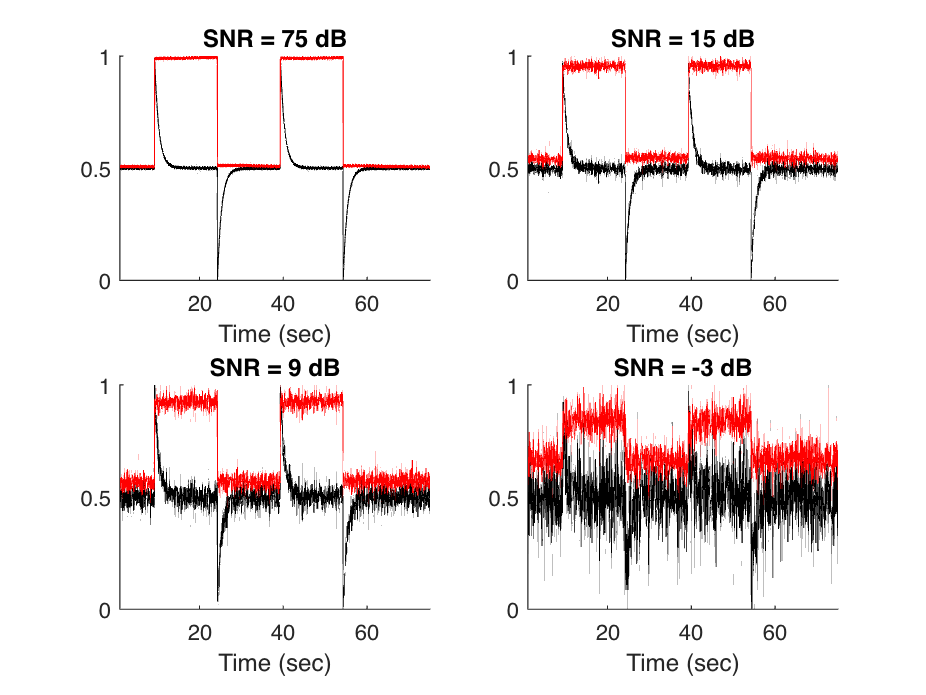



% Set noise levels
noise_levels = [.1, 1e2, 2e2, 8e2];
n=1;
figure

for i = noise_levels
    
    % Make noisy signal, deconvolve, and plot
    noise = randn(size(signal))*i;
    noisy_signal = signal + noise;
    noisy_signal = noisy_signal - mean(noisy_signal);

    noisy_deconv = deconv(noisy_signal, unit_impulse_response);
    r = snr(signal, noise);

    subplot(2,2,n); hold('on')
    title(['SNR = ', num2str(round(r)), ' dB'])
    plot_signal(normalize(noisy_signal(1:20:end), 'range'), output.sample_rate/10, 'sec', 'k')
    plot_signal(normalize(noisy_deconv(1:20:end), 'range', [0.5,1]), output.sample_rate/10, 'sec', 'r')
    xlim([1, 150/2])
    n = n + 1;
end